# Transverse-Shear Locking in Timoshenko beam elements - Cantilever Beam Subject to Vertical Distributed Load

## Introduction

This chapter investigates the transverse-shear locking that is exhibited by the low-order Finite Element discretizations of the [Timoshenko beam theory](https://en.wikipedia.org/wiki/Timoshenko%E2%80%93Ehrenfest_beam_theory) for the setup of a cantilever beam subject to vertical distributed load $\overline{q}$, see the following figure:

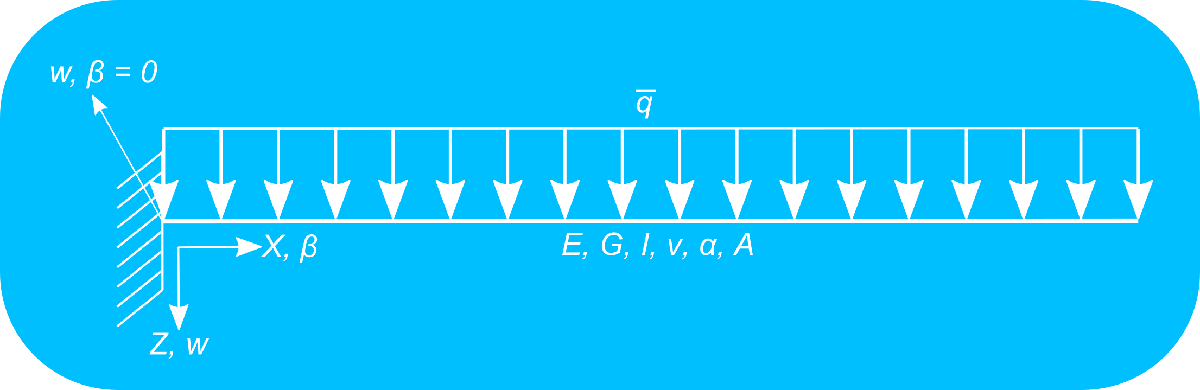

For this problem setup there is an analytical solution both in terms of the vertical deflection and the cross-sectional rotation, see the corresponding [derivation](matlab:open('../../2_TimoshenkoBeam/main_Chapter2_ALinearStraightTimoshenkoBeamElement.mlx')) at the Live Script [`main_Chapter2_ALinearStraightTimoshenkoBeamElement.mlx`](matlab:open('../../2_TimoshenkoBeam/main_Chapter2_ALinearStraightTimoshenkoBeamElement.mlx')) for more information.

It is used both linear and quadratic one-dimensional Finite Element formulations for the discretization of the variational formulation of the Timoshenko beam problem as this is shown in the Live Script [`main_Chapter1_ALinearStraightTimoshenkoBeamElement.mlx`](matlab:open('../../2_TimoshenkoBeam/main_Chapter2_ALinearStraightTimoshenkoBeamElement.mlx')). It is highlighted the transverse-shear locking that is exhibited by means of the linear one-dimensional Finite Element formulation. This appears not to be the case for the quadratic one-dimensional Finite Element formulation judging from the solution in terms of the vertical deflection and cross-sectional rotation.

It is afterwards shown, that the resultant transverse-shear forces obtained by both the linear and the quadratic Finite Element formulations is oscillatory. As reference solution it is used the solution obtained by the [Euler-Bernoulli](https://en.wikipedia.org/wiki/Euler%E2%80%93Bernoulli_beam_theory) beam problem discretized using the [Hermitian third-order basis functions](https://en.wikipedia.org/wiki/Cubic_Hermite_spline) and the analytical solution for this particular problem.

It is highlighted, that the use of selective-reduced integration can be productively used to alleviate locking, however the computation of the resultant transverse-shear forces demonstrates yet even more oscillatory behavior.

Finally, a mesh convergence study is performed for all aforementioned formulations and it is shown, that the Finite Element formulations using selective-reduced integration are associated with the highest convergence rates.

[PREVIOUS Chapter](matlab:open('../../3_ReissnerMindlinPlate/main_Chapter3_AShearDeformablePlateElement.mlx')) *Finite Element Formulation of the linear Reissner-Mindlin Plate*

[NEXT Chapter](matlab:open('../4_TransverseShearLocking_ReissnerMindlinCantileverPlate/main_Chapter4_Locking_ReissnerMindlinCantileverPlate.mlx')) *Transverse Shear Locking in Shear-Deformable Plates *`-`* Cantilever Plate Subject to Vertical Distributed Load*

**Author: Andreas Apostolatos, PhD (aapostol@mathworks.com)**

**Date: 20.02.2023**

## Preamble

clc;
clear;
close all;
tic;

## **Problem parameters**

### Geometric parameters

Thickness [m]

propStr.t = 10^(-1);

Width [m]

propStr.b = .1;

Height [m^2]

propStr.A = propStr.b*propStr.t;

X-coordinate at the left end of the beam [m]

X0 = 0;

Y-coordinate at the right end of the beam [m]

XL = 4;

### Material paramerters

Distributed load along the beam's length [N/m^2]

propStr.qBar = -1e4*(propStr.t)^3;

Distributed moment along the beam's length [N/m]

propStr.mBar = 0;

Boundary force [N]

propStr.Q = 0;

Boundary moment [Nm]

propStr.M = 0;

Young's modulus [N/m^2]

propStr.E = 1e7;

Poisson ratio [dimensionless]

propStr.nu = 0.3;

Moment of inertia [m^4]

propStr.I = propStr.b*(propStr.t^3)/12;

Shear modulus (connected to epsilon_12 = E/(1+nu)) [N/m^2]

propStr.G = propStr.E/(2*(1 + propStr.nu));

Shear correction factor [dimensionless]

propStr.alpha = 5/6;

## Analytical solution

### Initialization of auxiliary variables

syms wEx(X) betaEx(X) QEx(X) Lsym qsym Gsym Acs alpha_scf ...
    Aqsym Esym Isym

### Analytical solution with respect to the vertical deflection

wEx(X) = (qsym*Lsym*X-qsym*X^2/2)/Gsym/(Aqsym) - ...
    (-qsym*X^4/24+qsym*Lsym*X^3/6-qsym*Lsym^2*X^2/4)/Esym/Isym;

### Analytical solution with respect to the cross-sectional rotation

Get the analytical solution of the rotational field by leveraging the Partial Differential Equation (PDE) of the problem and the functions of the [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html)™ in [MATLAB](https://www.mathworks.com/products/matlab.html)®


$$\beta(X) = \int_{0}^L - \frac{1}{\alpha G A}\overline{Q} - \frac{\text{d}^2 w}{\text{d} x^2} \: \text{d}x \quad \quad (1)$$


betaEx(X) = int(-1/(propStr.alpha*propStr.G*propStr.A)*propStr.qBar - ...
    diff(diff(wEx, X), X));

### Evaluation of the expressions for the given geometric and material parameters

QEx(X) = alpha_scf*Gsym*Acs*(diff(wEx(X), X, 1) + betaEx(X));

### Evaluation of the expressions for the given geometric and material parameters

wEx(X) = subs(wEx,{Lsym, qsym, Gsym, Esym, Isym, Aqsym}, ...
    {XL, propStr.qBar, propStr.G, propStr.E, ...
    propStr.b*(propStr.t^3)/12, ...
    propStr.alpha*propStr.b*propStr.t});
betaEx(X) = subs(betaEx,{Lsym, qsym, Gsym, Esym, Isym, Aqsym}, ...
    {XL, propStr.qBar, propStr.G, propStr.E, ...
    propStr.b*(propStr.t^3)/12, ...
    propStr.alpha*propStr.b*propStr.t});
QEx(X) = subs(QEx, {alpha_scf, Gsym, Acs, Lsym, qsym, Gsym, Esym, ...
    Isym, Aqsym}, {propStr.alpha, propStr.G, propStr.A,XL, ...
    propStr.qBar, propStr.G, propStr.E, propStr.b*(propStr.t^3)/12, ...
    propStr.alpha*propStr.b*propStr.t});

  **Try**

Plot the exact shear-force distribution along the beam using function [`fplot`](https://www.mathworks.com/help/matlab/ref/fplot.html). Are the results as expected for the setup at hand?

 **Reflect**

It is expected, that the shear force distribution is linear with its maximum at the clamped edge while the resultant shear force at the free end of the beam should be zero, see the following figure,

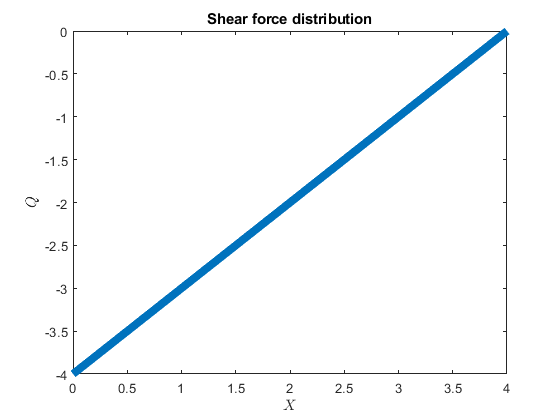

## Analytical expressions for the one-dimensional basis functions

### Analytical expressions for the linear basis functions

syms N1L1(xi) N2L1(xi)
N1L1(xi) = (1 - xi)/2;
N2L1(xi) = (1 + xi)/2;
NL1 = [N1L1 N2L1];

### Analytical expressions for the quadratic basis functions

syms N1L2(xi) N2L2(xi) N3L2(xi)
N1L2(xi) = (xi*(xi - 1))/2;
N2L2(xi) = (xi*(xi + 1))/2;
N3L2(xi) = 1 - xi^2;
NL2 = [N1L2 N2L2 N3L2];

## **Discretization**


$$\begin{array}{l}
w\left(X\right)\approx \sum_{i=1:N} N_i^w \;w_i ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\ldotp 1\right)\\
\beta \left(X\right)\approx \sum_{i=1:N} N_i^{\beta } \;\beta_i \;\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\ldotp 2\right)
\end{array}$$


### One-dimensional mesh using linear two-noded elements

#### Mesh generation

numElL1 = 6;
mshL1 = generateLinearMeshOnLine(X0, XL, numElL1);
numNodesL1 = numel(mshL1.nodes);

#### **Dirichlet boundary conditions**

freeDOFsL1 = 1:2*numNodesL1;
numDOFsL1 = 2*numNodesL1;
homDOFsL1 = 1:2;
[~, idxL1] = ismember(homDOFsL1, freeDOFsL1);
freeDOFsL1(idxL1) = [];

#### Mesh plot

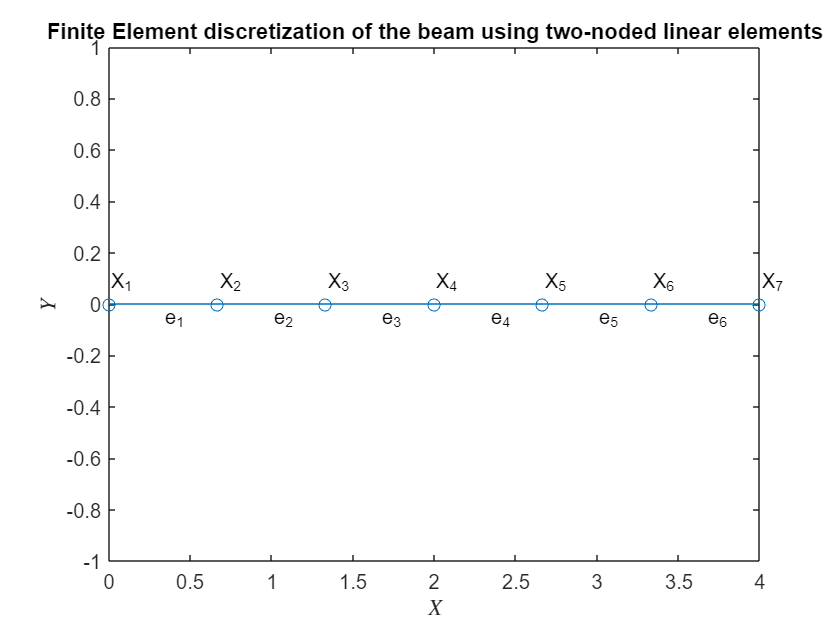

plotMesh1d(mshL1);
xlabel("$X$", Interpreter="latex")
ylabel("$Y$", Interpreter="latex")
title("Finite Element discretization of the beam using " + ...
    "two-noded linear elements")

### One-dimensional mesh using quadratic three-noded elements

#### Mesh generation

mshL2 = generateQuadraticMeshOnLine(mshL1);
numNodesL2 = numel(mshL2.nodes);

#### **Dirichlet boundary conditions**

freeDOFsL2 = 1:2*numNodesL2;
numDOFsL2 = 2*numNodesL2;
homDOFsL2 = 1:2;
[~, idxL2] = ismember(homDOFsL2, freeDOFsL2);
freeDOFsL2(idxL2) = [];

#### Mesh plot

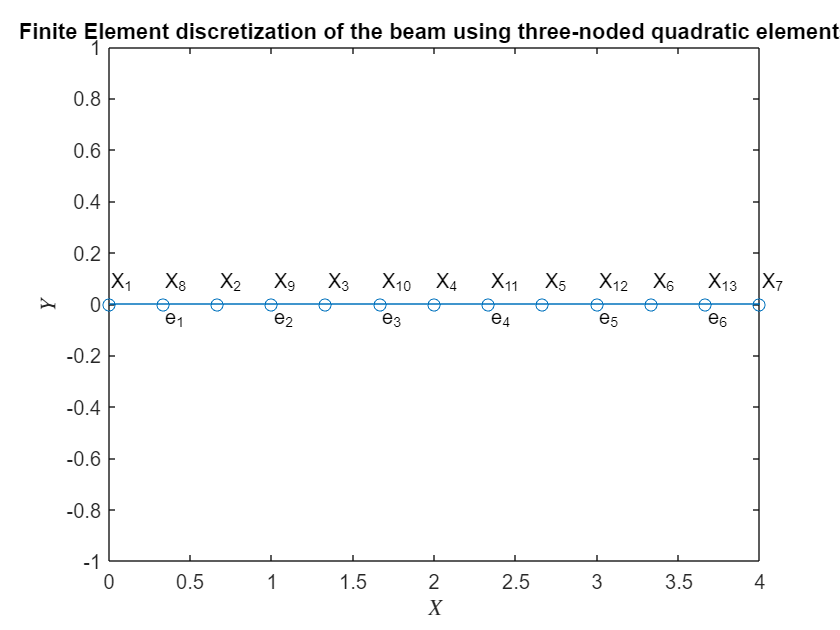

plotMesh1d(mshL2)
xlabel("$X$", Interpreter="latex")
ylabel("$Y$", Interpreter="latex")
title("Finite Element discretization of the beam using " + ...
    "three-noded quadratic elements")

## **Master stiffness matrices and master consistent nodal force vectors**

### **Linear finite elements and full integration**

#### Master stiffness matrix and load vector

computeStiffMatrixandForceVectorTB = ...
    @computeElementStiffMatrixandForceVectorTimoshenkoBeam;
computeBasisFunctionsAndDerivs = ...
    @computeLinearBasisFunctionsAndFirstDerivatives;
dummyInp = 'undefined';
[KL1, FL1body] = computeMasterStiffMatrixandForceVectorTimoshenkoBeam ...
    (mshL1, computeStiffMatrixandForceVectorTB, ...
    computeBasisFunctionsAndDerivs, dummyInp, propStr);

#### **Nodal force vector corresponding to boundary forces**

FL1boundary = zeros(2*numNodesL1, 1);
FL1boundary(end - 1, 1) = propStr.Q;
FL1boundary(end, 1) = propStr.M;

#### Total force vector as a sum of the body-force vector corresponding to distributed loads and the body-force vector corresponding to boundary loads

FL1 = FL1body + FL1boundary;

#### Sparsity of the master stiffness matrix using linear finite elements corresponding to the full integration

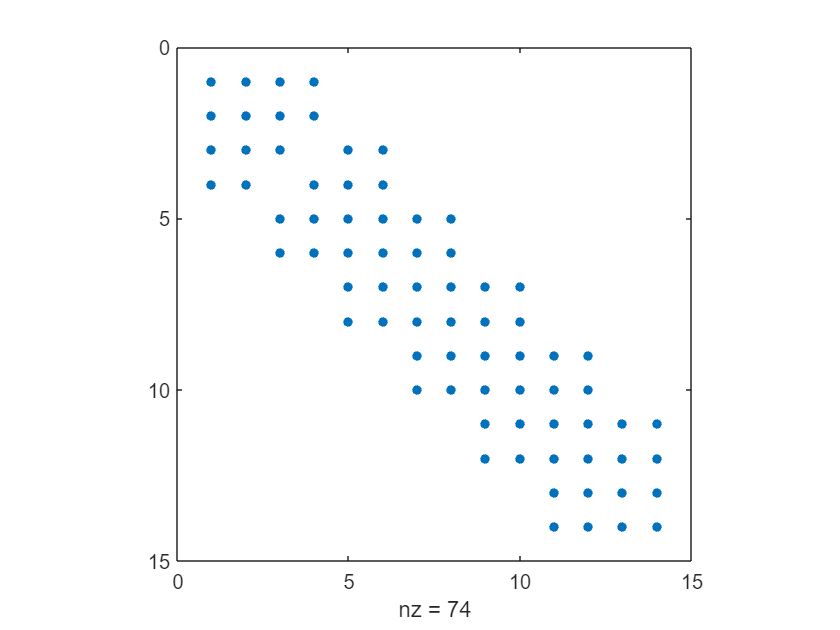

spy(KL1)

### **Linear finite elements and reduced integration**

#### Master stiffness matrix and load vector

computeStiffMatrixandForceVectorTB = ...
    @computeElementStiffMatrixandForceVectorTimoshenkoBeamRI;
computeBasisFunctionsAndDerivs = ...
    @computeLinearBasisFunctionsAndFirstDerivatives;
dummyInp = 'undefined';
[KL1RI, FBodyL1RI] = computeMasterStiffMatrixandForceVectorTimoshenkoBeam ...
    (mshL1, computeStiffMatrixandForceVectorTB, ...
    computeBasisFunctionsAndDerivs, dummyInp, propStr);

#### **Nodal force vector corresponding to boundary forces**

FL1BoundaryRI = zeros(2*numNodesL1, 1);
FL1BoundaryRI(end - 1, 1) = propStr.Q;
FL1BoundaryRI(end, 1) = propStr.M;

#### Total force as a sum of the body-force vector corresponding to distributed loads and the body-force vector corresponding to boundary loads

FL1RI = FBodyL1RI + FL1BoundaryRI;

#### Sparsity of the master stiffness matrix using linear finite elements corresponding to the full integration

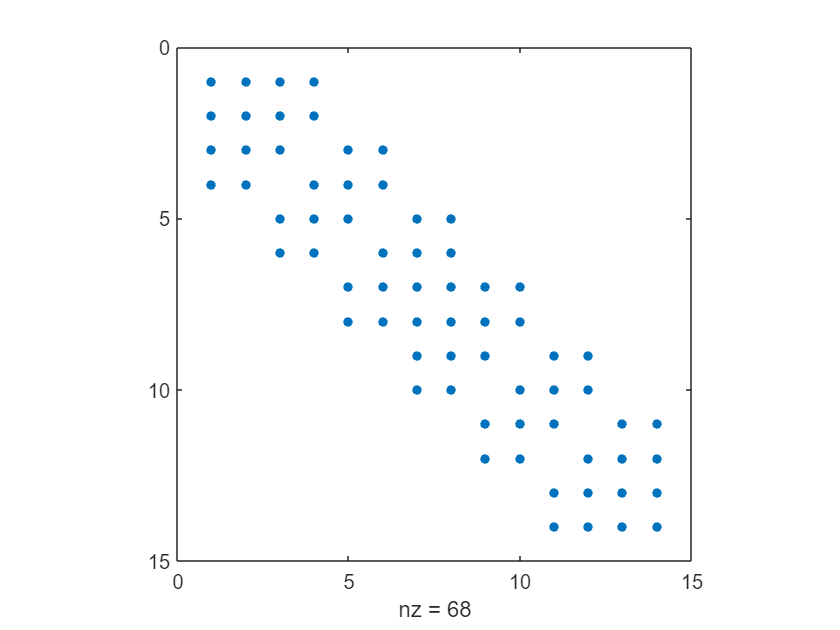

spy(KL1RI)

### **Quadratic finite elements and full integration**

#### Master stiffness matrix and load vector

computeStiffMatrixandForceVectorTB = ...
    @computeElementStiffMatrixandForceVectorTimoshenkoBeam;
computeBasisFunctionsAndDerivs = ...
    @computeQuadraticBasisFunctionsAndFirstDerivatives;
dummyInp = 'undefined';
[KL2, FBodyL2] = ...
    computeMasterStiffMatrixandForceVectorTimoshenkoBeam ...
    (mshL2, computeStiffMatrixandForceVectorTB, ...
    computeBasisFunctionsAndDerivs, dummyInp, propStr);

#### **Nodal force vector corresponding to boundary forces**

FBoundaryL2 = zeros(2*numNodesL2, 1);
FBoundaryL2(2*numNodesL1 - 1, 1) = propStr.Q;
FBoundaryL2(2*numNodesL1, 1) = propStr.M;

#### Total force vector as a sum of the body-force vector corresponding to distributed loads and the body-force vector corresponding to boundary loads

FL2 = FBodyL2 + FBoundaryL2;

#### Sparsity of the master stiffness matrix using linear finite elements corresponding to the full integration

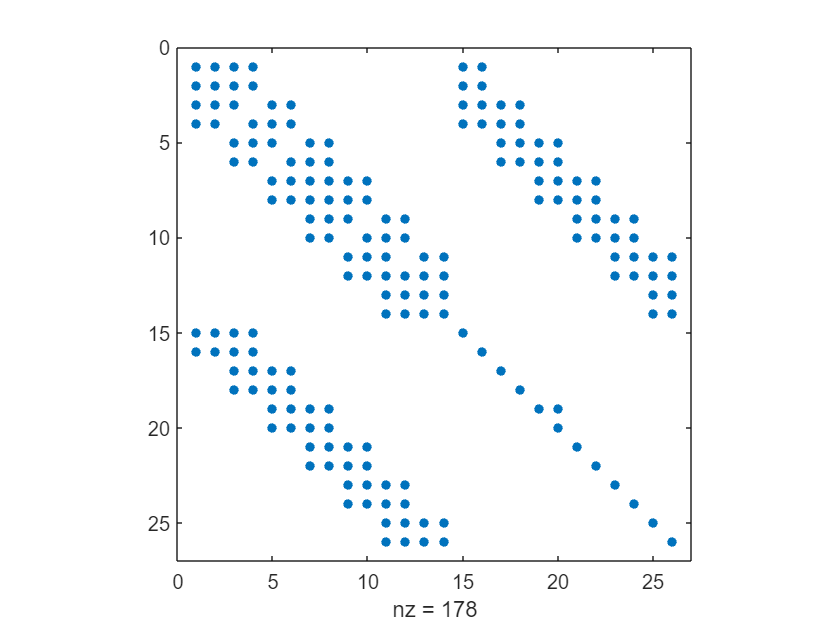

spy(KL2)

### **Quadratic finite elements and reduced integration**

#### Master stiffness matrix and load vector

computeStiffMatrixandForceVectorTB = ...
    @computeElementStiffMatrixandForceVectorTimoshenkoBeamRI;
computeBasisFunctionsAndDerivs = ...
    @computeQuadraticBasisFunctionsAndFirstDerivatives;
dummyInp = 'undefined';
[KL2RI, FBodyL2RI] = ...
    computeMasterStiffMatrixandForceVectorTimoshenkoBeam ...
    (mshL2, computeStiffMatrixandForceVectorTB, ...
    computeBasisFunctionsAndDerivs, dummyInp, propStr);

#### **Nodal force vector corresponding to boundary forces**

FBoundaryL2RI = zeros(2*numNodesL2, 1);
FBoundaryL2RI(2*numNodesL1 - 1, 1) = propStr.Q;
FBoundaryL2RI(2*numNodesL1, 1) = propStr.M;

#### Total force vector as a sum of the body-force vector corresponding to distributed loads and the body-force vector corresponding to boundary loads

FL2RI = FBodyL2RI + FBoundaryL2RI;

#### Sparsity of the master stiffness matrix using linear finite elements corresponding to the full integration

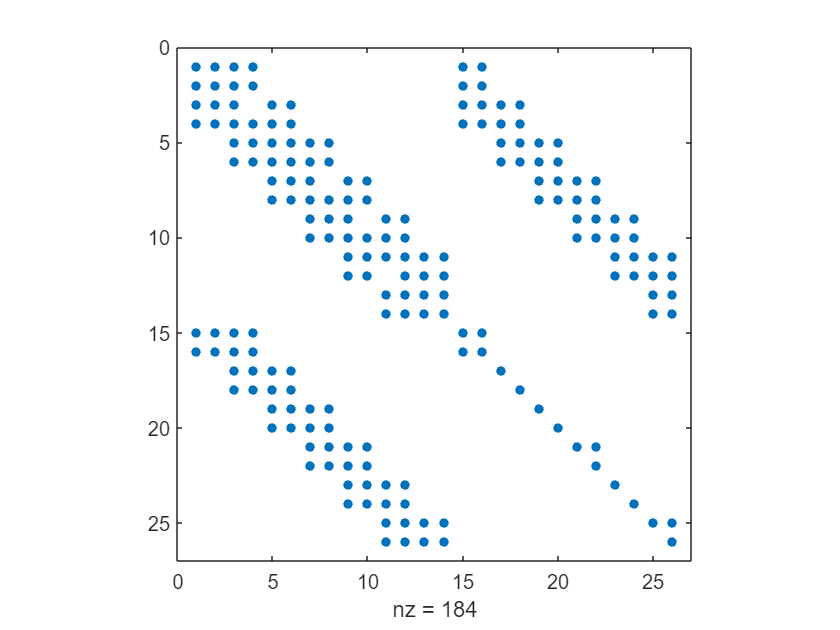

spy(KL2RI)

### Euler-Bernoulli formulation and Hermitian third-order basis functions

#### Master stiffness matrix and load vector

propStrEB = propStr;
propStrEB.q = propStr.qBar;
propStrEB.m = propStr.mBar;
computeStiffMatrixandForceVectorEBT = ...
    @computeElementStiffMatrixandForceVectorEulerBernoulliBeam;
[KEB, FBodyEB] = ...
    computeMasterStiffMatrixandForceVectorEulerBernoulliBeam ...
    (mshL1, computeStiffMatrixandForceVectorEBT, propStrEB);

#### **Nodal force vector corresponding to boundary forces**

FBoundaryEB = zeros(2*numNodesL1, 1);
FBoundaryEB(end - 1, 1) = propStr.Q;
FBoundaryEB(end, 1) = - propStr.M;

#### Total force vector as a sum of the body-force vector corresponding to distributed loads and the body-force vector corresponding to boundary loads

FEB = FBodyEB + FBoundaryEB;

#### Sparsity of the master stiffness matrix using linear finite elements corresponding to the full integration

spy(KEB)

## Solution of the Timoshenko beam problem

### Linear finite elements and full integration

uL1 = zeros(numDOFsL1, 1);
uL1(freeDOFsL1, 1) = KL1(freeDOFsL1, freeDOFsL1)\FL1(freeDOFsL1);

### Linear finite elements and selective-reduced integration

uL1RI = zeros(numDOFsL1, 1);
uL1RI(freeDOFsL1, 1) = KL1RI(freeDOFsL1, freeDOFsL1)\FL1RI(freeDOFsL1);

### Quadratic finite elements and full integration

uL2 = zeros(numDOFsL2, 1);
uL2(freeDOFsL2, 1) = KL2(freeDOFsL2, freeDOFsL2)\FL2(freeDOFsL2);
[nodesL2, idx] = sort(mshL2.nodes);
wL2 = uL2(1:2:end, 1);
betaL2 = uL2(2:2:end, 1);

### Quadratic finite elements and reduced integration

uL2RI = zeros(numDOFsL2, 1);
uL2RI(freeDOFsL2, 1) = KL2RI(freeDOFsL2, freeDOFsL2)\FL2RI(freeDOFsL2);
wL2RI = uL2RI(1:2:end, 1);
betaL2RI = uL2RI(2:2:end, 1);

### Euler-Bernoulli formulation with Hermitian third-order basis functions

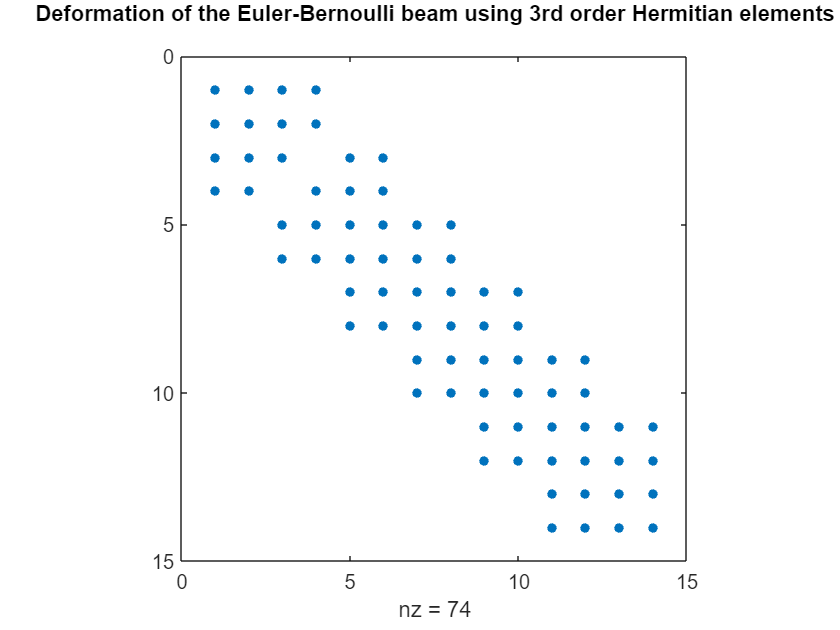

uEB = zeros(numDOFsL1, 1);
uEB(freeDOFsL1, 1) = KEB(freeDOFsL1, freeDOFsL1)\FEB(freeDOFsL1);
title(["Deformation of the Euler-Bernoulli beam using " + ...
    "3rd order Hermitian elements" ""])

### Postprocessing the solution

#### Visualization of the deformed configuration

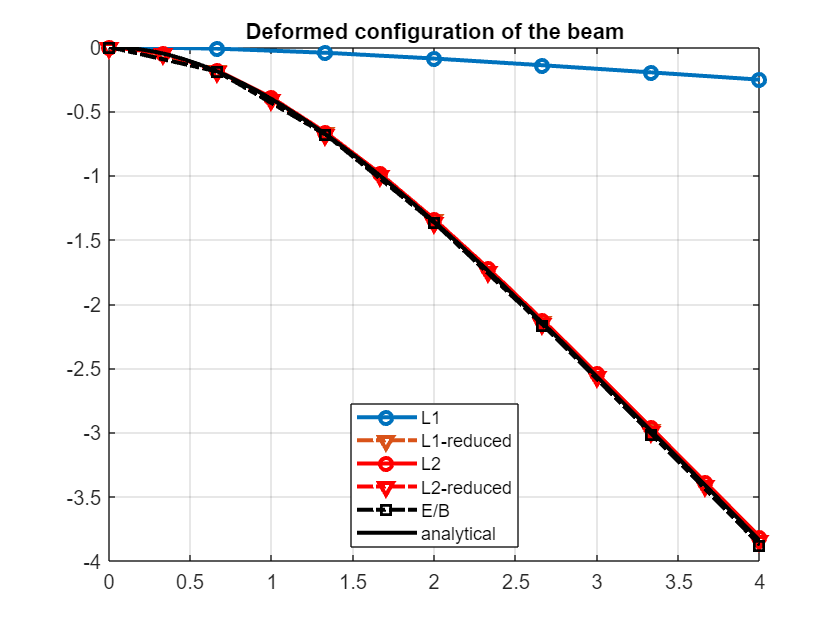

plot(mshL1.nodes, uL1(1:2:end, 1), '-o', LineWidth=2)
hold on;
plot(mshL1.nodes, uL1RI(1:2:end, 1), '-.v', LineWidth=2);
plot(nodesL2, wL2(idx), '-ro', LineWidth=2);
plot(nodesL2, wL2RI(idx), '-.rv', LineWidth=2);
plot(mshL1.nodes, uEB(1:2:end, 1), '-.ks', LineWidth=2);
fplot(wEx, [X0 XL], '-k', LineWidth=2);
hold off;
grid on;
legend("L1", "L1-reduced", "L2", "L2-reduced", "E/B", "analytical", ...
    Location="best")
title("Deformed configuration of the beam")

#### Visualization of the cross-sectional rotation field

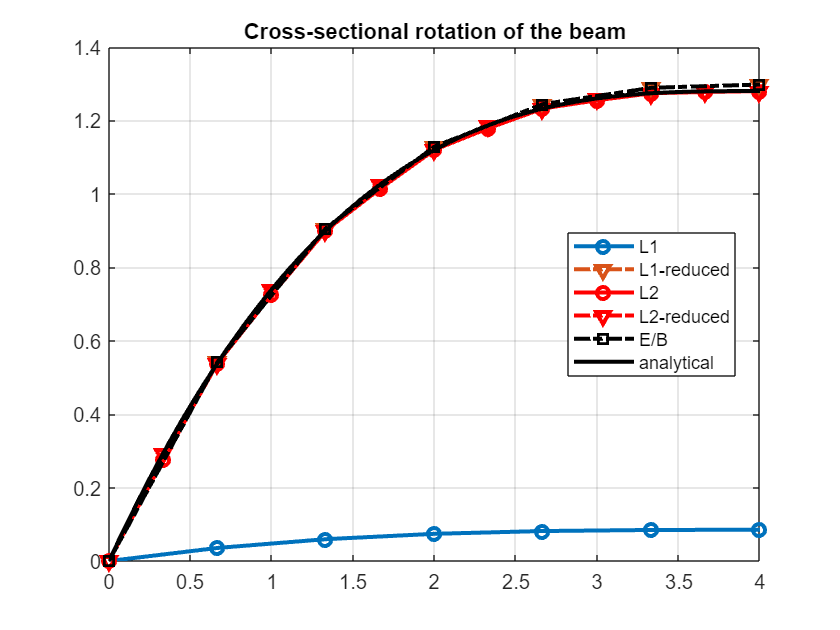

plot(mshL1.nodes, uL1(2:2:end, 1), '-o', LineWidth=2)
hold on;
plot(mshL1.nodes, uL1RI(2:2:end, 1), '-.v', LineWidth=2);
plot(nodesL2, betaL2(idx), '-ro', LineWidth=2);
plot(nodesL2, betaL2RI(idx), '-.rv', LineWidth=2);
plot(mshL1.nodes, -uEB(2:2:end, 1), '-.ks', LineWidth=2);
fplot(betaEx, [X0 XL], '-k', LineWidth=2);
hold off;
grid on;
legend("L1", "L1-reduced", "L2", "L2-reduced", "E/B", "analytical", ...
    Location="best")
title("Cross-sectional rotation of the beam")

## Transverse-shear locking due incompatible discretization spaces

Using the same polynomials basis functions for the discretization of the vertical displacement and rotation fields leads to a discretization space for the transverse shear forces that by construction does not contain zero transverse shear forces, namely:$\gamma = \frac{\text{d}w}{\text{d}x} + \beta = \sum_{i=1}^n \overbrace{\frac{\text{d}N_i^w(\xi)}{\text{d}x}}^{\text{constant}} w_i + \sum_{i = 1}^n \overbrace{N_i^{\beta}(\xi)}^{\text{linear}} \beta_i$

This fact is a direct consequence of the summation of piecewise polynomial functions with their derivatives which cannot be identically zero. The residual transverse-shear strains are then scaled by the material and geometric parameters to obtain the transverse-shear forces, namely:


$$Q = \alpha G A \gamma = \alpha G A \overbrace{\left(\frac{\text{d} w}{\text{d} x} + \beta\right)}^{\gamma}$$


which amplifies this numerical effect disproportionally as the thickness goes to zero $t \rightarrow 0$ (negligible shear deformations) as compared to the bending part that is scaled by $Eb t^3/12$.This is know as transverse shear-locking for shear-deformable thin-walled structures. Increasing the polynomial order reduces this effect but does not entirely remove it. 

In this section the transverse-shear force $Q$ is computed using linear and quadratic one-dimensional elements along with their counterparts when using selective-reduced integration along the beam. The solutions are compared to the transverse shear force distribution when using the Euler-Bernoulli beam formulation.

### Number of evaluation points for the transverse-shear forces

numPts = 50;

  **Try**

Modify the number of evaluation points by means of variable `numPts`

 **Reflect**

- How do the different distributions of the transverse-shear force change with respect to the number of evaluation points and why?

- How many evaluation points do you need to appropriately describe the different transverse-shear force distributions? Is this value constant or does it depend on the chosen value for the beam's length and thickness, $L$ and $t$, respectively?

### Transverse-shear force distribution along the beam's length

Navigate to [THIS](matlab:open('./main_Chapter41_TimoshenkoBeamLocking_ShearForces.mlx')) section for the detailed analysis.

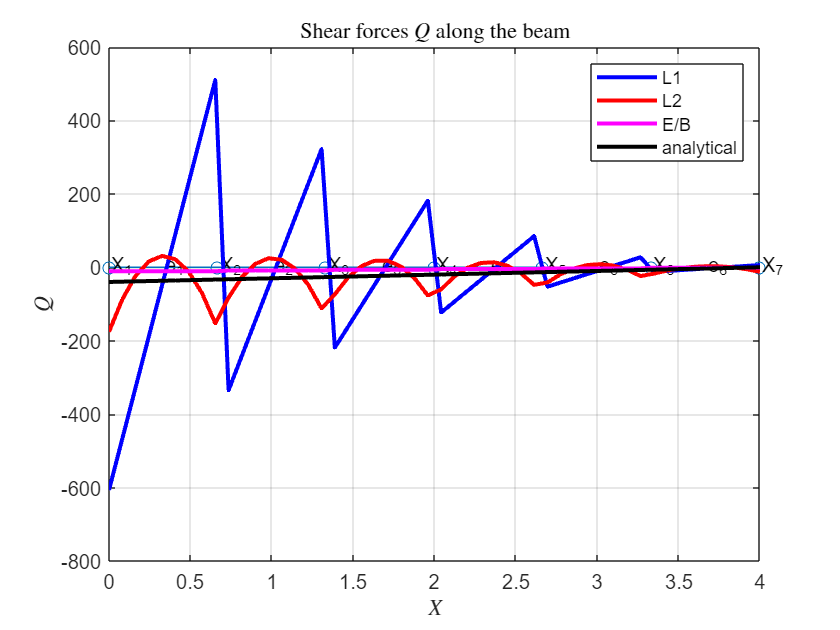

main_Chapter41_TimoshenkoBeamLocking_ShearForces

## Convergence study on transverse shear-locking

In this section it is shown how the rate of the mesh convergence study is reduced down due to transverse shear locking. The effect gets more pronounced the more slender the beam is.

### Number of refinement levels

numEl = 38;
if floor(numEl) ~= numEl
    error("Variable 'numRef' must be an integer")
end
if numEl <= 0
    error("Variable 'numRef' must be strictly positive")
end

  **Try**

Modify the number of refinement steps by means of variable `numRef`

 **Reflect**

- Keep the slenderness of the beam small enough $\lambda = \frac{L}{t} \in \mathcal{O}(1)$. What is the critical number of elements beyond which no variation in the tip deflection of the beam is observed?

- Increase the slenderness of the beam to $\lambda \in \mathcal{O}(10^{-2})$. What is the critical number of elements beyond which no variation in the tip deflection of the beam is observed? Note that you may need to increase the number of refinements by means of variable `numRef` to observe convergence

### Convergence study based on the tip displacement of the beam

Navigate to [THIS](matlab:open('./main_Chapter42_TimoshenkoBeamLocking_ConvergenceStudy.mlx')) section for the detailed analysis.

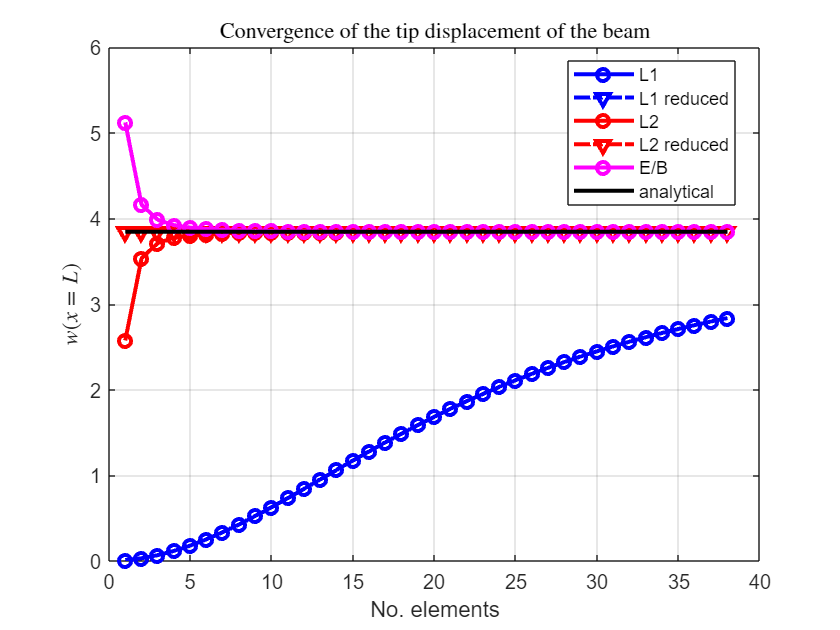

main_Chapter42_TimoshenkoBeamLocking_ConvergenceStudy

## References

[[1] Öchsner, Andreas. *Classical beam theories of structural mechanics*. Cham: Springer, 2021.](https://doi.org/10.1007/978-3-030-76035-9)

[[2] Hughes, Thomas JR. *The finite element method: linear static and dynamic finite element analysis*. Courier Corporation, 2012.](https://doi.org/10.1111/j.1467-8667.1989.tb00025.x)